# ENERGI322: Introduction to the buffeting theory

## Background

### Learning outcomes

The learning outcomes are statements that describe what students should know, understand, or be able to do by the end of the course. They specify the intended knowledge, skills, and competencies that students are expected to acquire and demonstrate.

**Knowledge**

Students will be able to:

- Define the Davenport wind loading chain.

- Explain the framework of the buffeting theory.

**Skills**

Students will be able to:

- Provide the expression for the aerodynamic damping for a single-degree of freedom (SDOF) system.

- Discuss the influence of damping on the wind-induced response.

- Assess the suitability of the frequency-domain approach and the time-domain approach for SDOF systems.

**Competences**

Students will be able to:

- Critically assess the limits of the buffeting theory.

- Propose improved structural designs based on the dynamic response simulation outputs.

### **The Davenport wind loading chain and the linearized buffeting theory**

The Davenport wind loading chain constitutes a systematic approach to  evaluating the wind load on structures. This methodology, developed by  Alan G. Davenport, integrates the effects of climate, terrain roughness, aerodynamics, structural dynamics, and design criteria to predict the  wind-induced forces accurately. It emphasizes the influence of multiple  factors that require knowledge of meteorology, aerodynamics, and  structural engineering. This chain model establishes the framework  necessary to design buildings and structures capable of withstanding  large wind-induced loads.

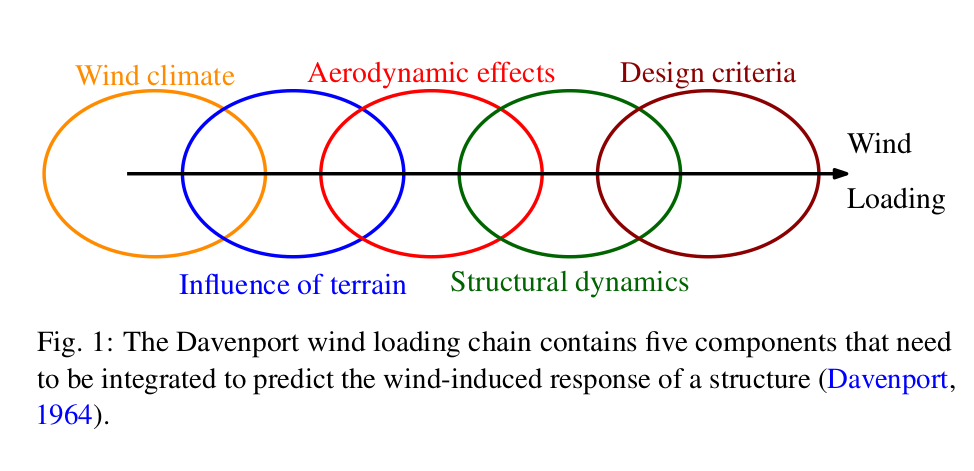

The turbulent wind-induced response of a structure can be studied using  the so-called "buffeting theory", which was introduced in the early  1960s by Davenport. The buffeting theory can be applied in either the  time domain or the frequency domain. For the latter, the analysis is  limited to linear loads and linear structural properties. In the time  domain, the wind load must be simulated as time histories, which is  computationally more expensive. However, this approach allows for easier consideration of non-linearities and non-stationarity. Hereinafter,  only the linear approach is presented. The following figure provides the framework of the buffeting theory. In this figure, the dynamic wind  velocity is transformed into the dynamic wind load via the aerodynamic  admittance function, and the dynamic response is obtained from the  dynamic wind load via the mechanical admittance function.

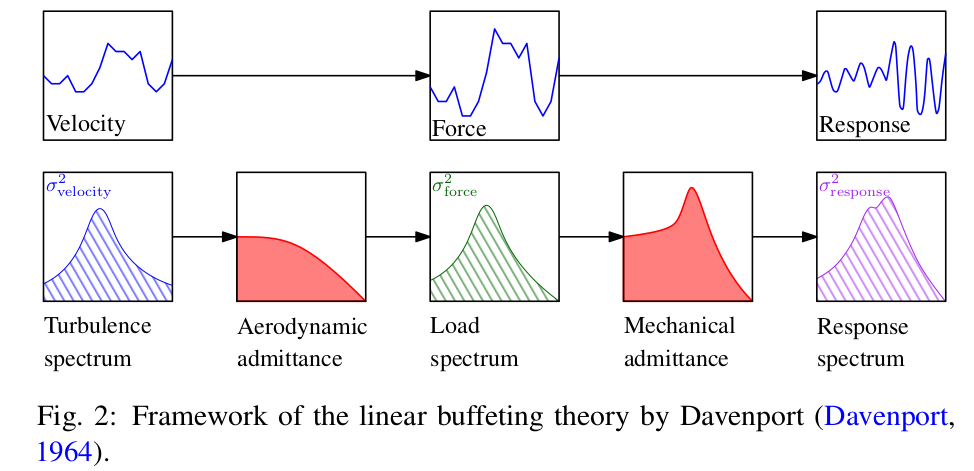

### **Structural model**

The equation for wind loading on a simplified Single Degree of Freedom (SDOF) system that only allows for lateral motion (one direction) is presented below and sketched in the figure. For simplicity, only the along-wind velocity component \(u\) is assumed to contribute to the structural dynamics. The equation describes the motion of a SDOF as a second-order differential equation, which represents the balance between inertial forces, damping forces, restoring forces, and external forces (wind forces in this case).


$$M\ddot{r}_x + C\dot{r}_x + K r_x = f_{\text{wind}}(t) $$


where M is the mass of the system; $\ddot{r}_x$ is the acceleration (second derivative of displacement x with respect to time; C is the damping coefficient; $\dot{r}_x$ is the velocity (first derivative of displacement x with respect to time); K is the stiffness of the system; $r_x$ is the lateral displacement and $f_{\text{wind}}$ is the lateral wind load as a function of time. In structural dynamics, the terms inertial force, damping force, and restoring forces are seldom used. Instead, these are simply grouped into a so-called mass-spring-damper system. The stiffness K and the damping coefficient C of a Single Degree of Freedom (SDOF) system can be expressed as functions of the natural frequency $\omega$ of the system and the damping ratio $\zeta$.


$$K  = \omega^2 M	\\
C  = 2\zeta\omega M $$


The damping ratio $\zeta$ is a dimensionless measure of damping in the system, indicating how rapidly oscillations decay due to the dissipation of energy. The damped eigenfrequency represents the eigenfrequency of the system once the damping is taken into account:


$$\omega_d = \omega \sqrt{1-\zeta^2}$$


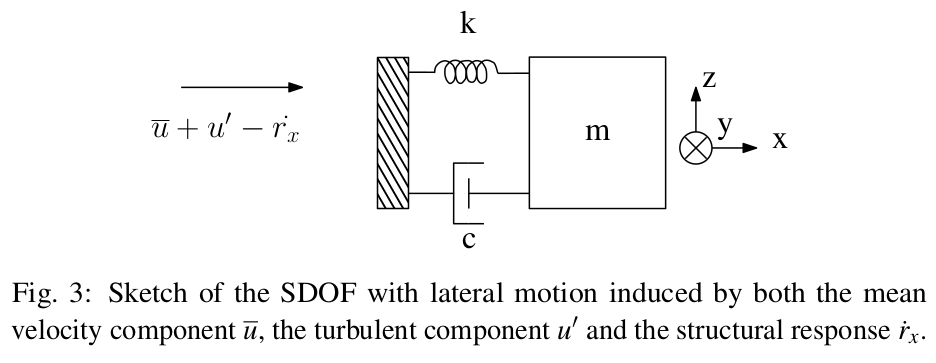

## Simulation

### Parameters used in the simulation setup

clearvars; close all; clc;

% Add path for external functions
addpath './functions'
% Initialize random number generator for reproducibility
rng(10)

% Modal parameters
fn = 0.2; % natural frequency
omega = fn * 2 * pi; % eigen-frequency (rad/s)
A = 0.2; % area in m^2
eta = 0.005; % damping ratio
wd = omega * sqrt(1 - eta^2); % damped eigen frequency (rad/s)
M = 100; % mass (kg)
K = omega^2 * M; % stiffness
C = 2 * eta * M * omega; % damping coefficient
Cd = 1; % drag force coefficient
rho = 1.225; % air density (kg/m^3)

% AAF model specification
modelAAF = 'Liepman';

% Turbulence simulation parameters
fs = 10; % sampling frequency (Hz)
dt = 1 / fs; % time step (s)
pow2 = 13; % M is the power of 2 for time steps (e.g., 2^M = 1024)
[t, f] = getSamplingPara(pow2, fs); % Obtain frequency and time vector

Duration of target time series is 0.228 hours, i.e. 819 sec 




% Parameters for the wind flow simulation
z0 = 0.1; % roughness length (m)
meanU = 20; % mean wind speed (m/s)
z = 30; % measurement height (m)


### Turbulence generation

% Calculate friction velocity
u_star = meanU * 0.40 ./ log(z / z0); 
% Compute reduced frequency
fr = f * meanU / z; 
% Calculate Target Power Spectral Density (PSD) for the along-wind component
Su = u_star^2 ./ f .* 102 .* fr ./ (1 + 33 .* fr).^(5/3); 
% Generate time histories of the turbulent fluctuations for the along-wind component
tic
[u, ~] = randomProcess(f, Su); 
toc

Elapsed time is 0.004918 seconds.


### Static response in the time domain

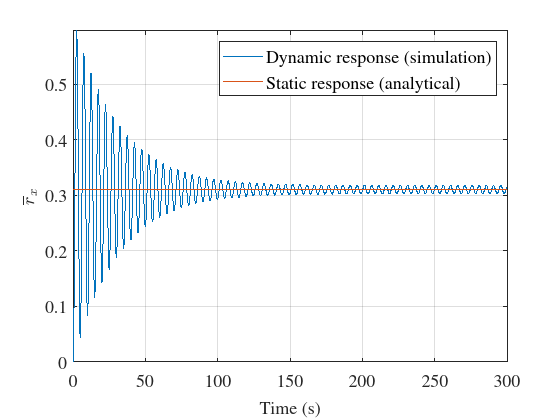

% Analytical solution for static displacement
r_static_analytic = rho * A * Cd * meanU^2 / (2 * K);

% Numerical solution for lateral responses using ODE45
method = 'linear';
[rx, drx, ddrx] =...
    getResponse1D_ODE45(t, 0.*u, meanU, A, Cd, rho, method, modelAAF, M, K, C);

% Plotting
figure; % Create figure window
plot(t, rx, 'linewidth', 1.2); % Plot lateral displacement response over time
hold on;
plot([t(1) t(end)], [r_static_analytic r_static_analytic],...
    'linewidth', 1.2); % Plot static response for comparison
ylabel('$\overline{r}_x$',...
    'interpreter', 'latex'); % Lateral displacement label
xlabel('Time (s)'); % Time label
legend('Dynamic response (simulation)',...
    'Static response (analytical)', 'orientation', 'vertical', 'location', 'northeast');
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Set font properties
grid on; % Enable grid for readability
axis tight; % Tighten axis limits
xlim([0 300]); % Set x-axis limits

### Dynamic response in the time domain

tic;
% Linear dynamic response
method = 'linear';
[rx, drx, ddrx] = ...
    getResponse1D_ODE45(t, u, meanU, A, Cd, rho, method, modelAAF, M, K, C);
% Non-linear dynamic response
method = 'non-linear';
[rx_NL, drx_NL, ddrx_NL] = ...
    getResponse1D_ODE45(t, u, meanU, A, Cd, rho, method, modelAAF, M, K, C);

toc;

Elapsed time is 1.591290 seconds.


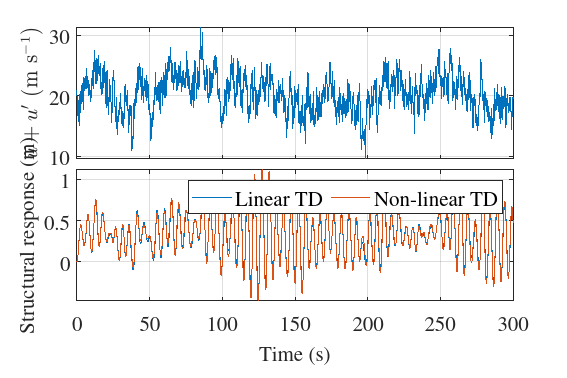


% Create a new figure window
figure('position', [541 430 750 500]);
tiledlayout(2, 1, "TileSpacing", "tight");
% Plot total wind speed
nexttile;
plot(t, u + meanU, 'linewidth', 1.2);
ylabel('$\overline{u} + u^\prime$ (m s$^{-1}$)',...
    'interpreter', 'latex');
grid on;
axis tight;
xlim([0 300]);
set(gca, 'XTickLabel', []);
% Plot structural responses
nexttile;
plot(t, rx, 'linewidth', 1.2);
hold on;
plot(t, rx_NL, 'linewidth', 1.2);
xlabel('Time (s)');
ylabel('Structural response (m)');
legend('Linear TD', 'Non-linear TD',...
    'orientation', 'horizontal', 'location', 'northeast');
grid on;
axis tight;
xlim([0 300]);
% Set figure and font properties
set(gcf, 'color', 'w');
set(findall(gcf, '-property', 'FontSize'),...
    'FontSize', 16, 'FontName', 'Times');

### Aerodyanmic admittance function (AAF)

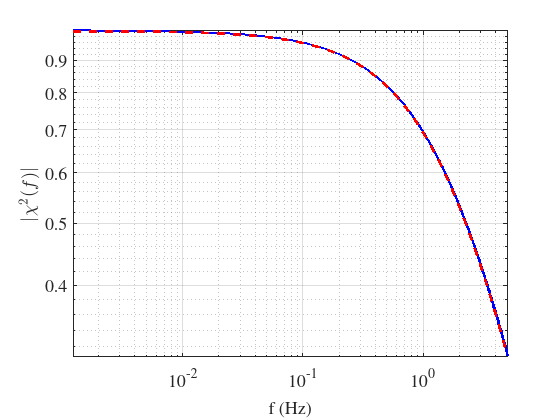

% Calculate sampling frequency and frequency vector
fs = 1/median(diff(t)); % Sampling frequency
N = numel(t); % Number of samples
f0 = 1/t(end); % Lowest frequency
f1 = 0:f0:(fs/2 + f0); % Frequency vector

% Apply AAF to the velocity data
B = sqrt(A); % Characteristic length
[u_filt] = applyAAF_TD(u, f1, meanU, B, modelAAF); 

% Estimate AAF from the time series
[d1, ~] = pwelch(detrend(u_filt), N, 1, N, fs);
[d2, f_chi] = pwelch(detrend(u), N, 1, N, fs);
Chi = d1 ./ d2;

% Calculate Liepman Aerodynamic admittance function
fr = f * B / meanU;
phi2 = 1 ./ (1 + 2 * pi^2 * fr);

% Plotting
figure;
loglog(f_chi, Chi, 'b', 'linewidth', 2); % Plot estimated AAF
hold on;
loglog(f, phi2, 'r--', 'linewidth', 2); % Plot Liepman AAF
xlabel('f (Hz)'); % Frequency label
ylabel('$|\chi^2(f)|$', 'interpreter', 'latex'); % AAF label
grid on;
axis tight;
set(gcf, 'color', 'w');
set(findall(gcf, '-property',...
    'FontSize'), 'FontSize', 14, 'FontName', 'Times');

### Dynamic response in the frequency domain

% Compute response without Aerodynamic Admittance Function (AAF)
[Sx_noAAF, Hmeca] = ...
    getResponse_FD(meanU, Su, rho, A, Cd, f, M, K, C, 'none');


% Compute response with specified AAF model
[Sx_withAAF, ~] = ...
    getResponse_FD(meanU, Su, rho, A, Cd, f, M, K, C, modelAAF);


### Mechanical admittance function

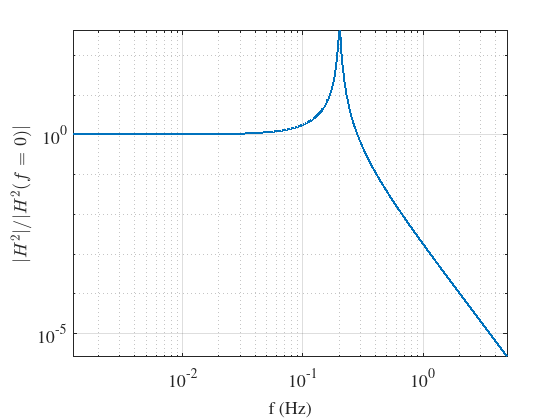

figure
% Plot the normalized mechanical admittance function
loglog(f, abs(Hmeca.^2) ./ abs(Hmeca(1).^2), 'linewidth', 2);

% Label the axes
xlabel('f (Hz)'); % Frequency axis label
ylabel('$|H^2|/|H^2(f =0)|$', 'interpreter',...
    'latex'); % Normalized mechanical admittance function label

% Improve plot readability
grid on; % Enable grid
axis tight; % Tighten axis limits
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 14,...
    'FontName', 'Times'); % Adjust font properties

### Time domain vs frequency domain

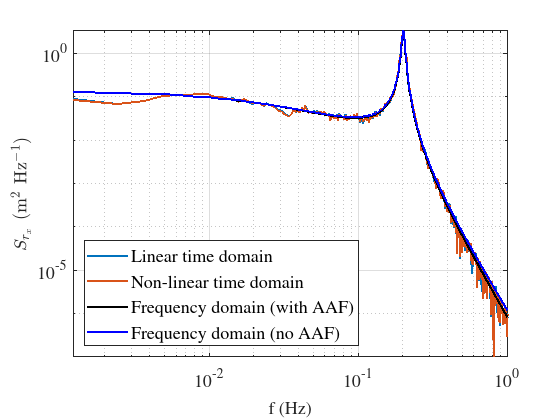

% Calculate spectral density for linear and non-linear responses in the time domain
N = numel(t);
[S_td, f_td] = pmtm(detrend(rx), 4, N, fs);
[S_td_NL, f_td_NL] = pmtm(detrend(rx_NL), 4, N, fs);

figure;
loglog(f_td, S_td, 'linewidth', 1.5); % Plot time domain linear response
hold on;
loglog(f_td_NL, S_td_NL, 'linewidth', 1.5); % Plot time domain non-linear response
loglog(f, Sx_withAAF, 'k', 'linewidth', 1.5); % Plot frequency domain response with AAF
loglog(f, Sx_noAAF, 'b', 'linewidth', 1.5); % Plot frequency domain response without AAF

% Labels and legend
xlabel('f (Hz)'); % Frequency axis label
ylabel('$S_{r_x}$ (m$^2$ Hz$^{-1}$)', 'interpreter', 'latex'); % Spectral density label
legend('Linear time domain', 'Non-linear time domain',...
    'Frequency domain (with AAF)', 'Frequency domain (no AAF)', 'location', 'southwest');
% Improve plot readability
grid on; % Enable grid
axis tight; % Tighten axis limits
set(gcf, 'color', 'w'); % Set figure background color
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 14, 'FontName', 'Times'); % Adjust font properties
xlim([0 1])

% Display standard deviation of lateral displacement responses
fprintf('STD of the lateral displacement response (TD-linear) is %2.3f m \n', sqrt(trapz(f_td, S_td)));

STD of the lateral displacement response (TD-linear) is 0.226 m 


fprintf('STD of the lateral displacement response (TD-nonlinear) is %2.3f m \n', sqrt(trapz(f_td_NL, S_td_NL)));

STD of the lateral displacement response (TD-nonlinear) is 0.234 m 


fprintf('STD of the lateral displacement response (FD) with AAF is %2.3f m \n', sqrt(trapz(f, Sx_withAAF)));

STD of the lateral displacement response (FD) with AAF is 0.226 m 


fprintf('STD of the lateral displacement response (FD) no AAF is %2.3f m \n', sqrt(trapz(f, Sx_noAAF)));

STD of the lateral displacement response (FD) no AAF is 0.234 m 
